## **Identify segments in regions without waves**

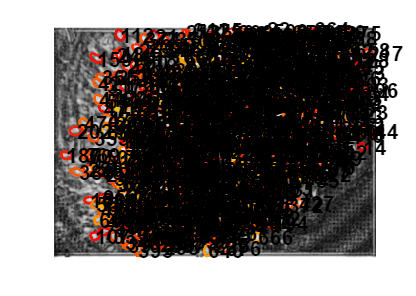

%% get contour information of all segments and create segment polyshapse
Coor = neuron.show_contours(0.9,(1:segment.seg),neuron.Cn,'true');

contour=neuron.Coor;
pseg{segment.seg}={};

for i=1:segment.seg
    pseg{i}=polyshape(contour{i,1}(1,:),contour{i,1}(2,:));
end 

### Get region(s) of the field of view with waves

numRegions = input("Please input the number of regions with waves: ");
A{numRegions}=[];

for x=(1:numRegions)
    
    numOfPoints = input("Please input the number of vertices for the region: ");
    pointsx = cell(1,numOfPoints);
    pointsy = cell(1,numOfPoints);

    for p=(1:numOfPoints)
        xval = input('Please input the (X-coordinate) of this vertex: ');
        yval = input('Please input the (Y-coordinate) of this vertex: ');
        pointsx{p}=xval;
        pointsy{p}=yval;
    end

    A{x} = polyshape(cell2mat(pointsx),cell2mat(pointsy));
end

if numRegions==1
    withWaves=A{numRegions};
else
    withWaves=A{numRegions};
    while numRegions>1
        withWaves=union(withWaves,A{numRegions-1});
        numRegions=numRegions-1;
    end
end

waveregions=A;

### Determine which segments are in regions without waves

seg0wave=[];
for j = 1:segment.seg
pout=subtract(withWaves,pseg{j});
if isequal(pout,withWaves)==1
seg0wave=[seg0wave,j];
else
end
end
seg0wave=setdiff(seg0wave,outliers);
% outliers: a variable with segments that have not been properly detected
% by CMNFe

### Determine which segments are in regions with waves

segwave=[1:segment.seg];
segwave=setdiff(segwave,seg0wave);
segwave=setdiff(segwave,outliers);

### Examine overlapping segments using spatial footprints

segoverlap=zeros(segment.seg);
for k=1:segment.seg
for l=1:segment.seg
pout=subtract(pseg{k},pseg{l});
segoverlap(k,l)=1-(area(pout)/area(pseg{k}));
end
end


### Reveal overlapping segments in regions without waves

nowaveoverlap={};
tick=1;
OLpercent = input("Please input the % for overlapping (0-100): ");
OLpercent = OLpercent/100;
for m=1:numel(seg0wave)
    for n=1:numel(seg0wave)
        if (segoverlap(seg0wave(m),seg0wave(n))>=OLpercent)&&(m~=n)
            nowaveoverlap{tick}=[seg0wave(m),seg0wave(n)];
            tick=tick+1;
        else
        end
    end
end


### Reveal overlapping segments in regions with waves

waveoverlap={};
tick=1;
for m=1:numel(segwave)
    for n=1:numel(segwave)
        if (segoverlap(segwave(m),segwave(n))>=OLpercent)&&(m~=n)
            waveoverlap{tick}=[segwave(m),segwave(n)];
            tick=tick+1;
        else
        end
    end
end


### Remove overlapped segments

seg0wave=setdiff(seg0wave,remove0wave);
segwave=setdiff(segwave,removewave);

### Save new data into the mat file

filename=horzcat(segment.mouseID,'_',segment.session,'.mat');
save(filename,"seg0wave","segwave","numRegions","contour","pseg","nowaveoverlap","waveregions","waveoverlap","OLpercent","withWaves","segoverlap","removewave","remove0wave",'-append');